syms x
format longg

%a)
fprintf('perturbare output');

a) PERTURBAM OUTPUT-UL:



input_matrix = [10 7 8 7;7 5 6 5;8 6 10 9;7 5 9 10];
output_matrix = [32;23;33;31];
perturbed_output = [32.1;22.9;33.1;30.9];

result = input_matrix\output_matrix;
perturbed_result = input_matrix\perturbed_output;

fprintf('result = input_matrix\\output_matrix: \n');

result = input_matrix\output_matrix: 


disp(result);

     1
     1
     1
     1



fprintf('\nperturbed_result = input_matrix\\perturbed_output: \n');


perturbed_result = input_matrix\perturbed_output: 


disp(perturbed_result);

          9.19999999999968
         -12.5999999999995
          4.49999999999986
         -1.09999999999992




%eroarea relativa e norma
eroare_intrare=norm(output_matrix-perturbed_output)/norm(output_matrix);
eroare_iesire=norm(result-perturbed_result)/norm(result);
raport = eroare_iesire/eroare_intrare;

fprintf('Eroare intrare: %f\n', eroare_intrare);

Eroare intrare: 0.003332


fprintf('Eroare iesire: %f\n', eroare_iesire);

Eroare iesire: 8.198475


fprintf('Raport: %f\n\n\n\n', raport);

Raport: 2460.567236







%b)
fprintf('perturbare input');

b) PERTURBAM INPUT-UL:


perturbed_input_matrix=[10 7 8.1 7.2;7.08 5.04 6 5;8 5.98 9.89 9;6.99 4.99 9 9.98];
perturbed_result = perturbed_input_matrix\output_matrix;

fprintf('result = input_matrix\\output_matrix: \n');

result = input_matrix\output_matrix: 


disp(result);

     1
     1
     1
     1



fprintf('\nperturbed_result = perturbed_input_matrix\\output_matrix: \n');


perturbed_result = perturbed_input_matrix\output_matrix: 


disp(perturbed_result);

         -80.9999999999311
          136.999999999886
         -33.9999999999704
          21.9999999999823




eroare_intrare=norm(output_matrix-perturbed_output)/norm(output_matrix);
eroare_iesire=norm(result-perturbed_result)/norm(result);
raport = eroare_iesire/eroare_intrare;

fprintf('Eroare intrare: %f\n', eroare_intrare);

Eroare intrare: 0.003332


fprintf('Eroare iesire: %f\n', eroare_iesire);

Eroare iesire: 81.984755


fprintf('Raport: %f\n', raport);

Raport: 24605.672364


syms x
format longg

for i=10:15
    %cond. matrice hilbert
    hilbert=hilb(i);
    c=cond(hilbert);
    
    %norma euclidiana
    n=norm(hilbert);
    
    %raport
    r=c/n;
    fprintf("i: %d raport:%d\n",i,r);
end

i: 10 raport:9.147075e+12
i: 11 raport:2.942033e+14
i: 12 raport:9165087956117182
i: 13 raport:7309846515501700096
i: 14 raport:111270145526842912
i: 15 raport:195821660632525984


syms x
format longg

fprintf("a) tk=-1+k*(2/n)\n");

a) tk=-1+k*(2/n)


for i=10:15
    fprintf('i= %d\n',i);
    %n puncte echidistante -> basically a calculat aici si t_k
    puncte_echidistante=linspace(-1,1,i);
    
    %vandermonde
    v=vander(puncte_echidistante);
    cond_vander = cond(v);
    fprintf('cond. vander: %f\n',cond_vander);
    
    %cebisev
    norm_chebisev=norm(v,'inf');
    fprintf('norm. chebise: %f\n\n',norm_chebisev);
end

i= 10


cond. vander: 4626.449923


norm. chebise: 10.000000



i= 11


cond. vander: 13951.626931


norm. chebise: 11.000000



i= 12


cond. vander: 40754.881842


norm. chebise: 12.000000



i= 13


cond. vander: 123389.737998


norm. chebise: 13.000000



i= 14


cond. vander: 363830.757691


norm. chebise: 14.000000



i= 15


cond. vander: 1104808.529364


norm. chebise: 15.000000





fprintf("b) tk=1/k\n");

b) tk=1/k


for i=10:15
    fprintf('i= %d\n',i);
    puncte_echidistante=1:1:i;
    
    %o sa fie un vector cu 1/fiecare punct echidistant
    t_k=1./puncte_echidistante;
    
    %vandermonde
    v=vander(puncte_echidistante);
    cond_vander = cond(v);
    fprintf('cond. vander: %f\n',cond_vander);
    
    %cebisev
    norm_chebisev=norm(v,'inf');
    fprintf('norm. chebise: %f\n\n',norm_chebisev);
end

i= 10


cond. vander: 2106257537155.242188


norm. chebise: 1111111111.000000



i= 11


cond. vander: 116446946393656.718750


norm. chebise: 28531167061.000000



i= 12


cond. vander: 7071899372800194.000000


norm. chebise: 810554586205.000000



i= 13


cond. vander: 467971140902740416.000000


norm. chebise: 25239592216021.000000



i= 14


cond. vander: 33513664782666625024.000000


norm. chebise: 854769755812155.000000



i= 15


cond. vander: 2582410742724318724096.000000


norm. chebise: 31278135027204240.000000



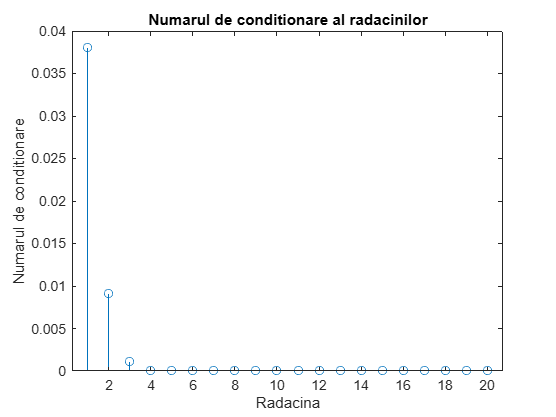

%polinomul (x - 1)(x - 2)...(x - n)
n = 20;
p = poly(1:n);

%radacinile
roots_exact = roots(p);

%calcul nr. de conditionare pt fiecare radacina
cond_numbers = zeros(n, 1);

%ca sa fie aleatoare normala dispersia
%ca sa fie uniforma:  unifrnd(1, n+1) * 1e-10
perturbation = normrnd(0,1e-10);

for i = 1:n
    p_perturbed = p;
    
    %de fiecare data perturb un coeficient
    p_perturbed(i) = p_perturbed(i) + perturbation;
    
    %aflam iar radacinile si conditionarea 
    %aka cat de mult o influentat perturbarea noastra rez final
    roots_perturbed = roots(p_perturbed);
    cond_numbers(i) = norm(roots_perturbed - roots_exact)/norm(roots_exact);
end

%graficul nr. de conditionare al fiecarei radacini
figure;
stem(1:n, cond_numbers);
title('Numarul de conditionare al radacinilor');
xlabel('Radacina');
ylabel('Numarul de conditionare');


%perturbarea cu variabile aleatoare normale
%init o perturbare care urmeaza distributie normala
perturbation_normal = normrnd(0,1e-10);
p_perturbed_normal = p + perturbation_normal;
roots_perturbed_normal = roots(p_perturbed_normal);
error_perturbed_normal = norm(roots_perturbed_normal-roots_exact)/norm(roots_exact);
fprintf('error with normal perturbation %f\n',error_perturbed_normal);

error with normal perturbation 0.058196



%perturbarea cu variabile aleatoare uniforme
%init o perturbare care urmeaza distributie uniforma
perturbation_uniform = unifrnd(1, n+1) * 1e-10;
p_perturbed_uniform = p + perturbation_uniform;
roots_perturbed_uniform = roots(p_perturbed_uniform);
error_perturbed_uniform = norm(roots_perturbed_uniform-roots_exact)/norm(roots_exact);
fprintf('error with uniform perturbation %f\n',error_perturbed_uniform);

error with uniform perturbation 0.070089


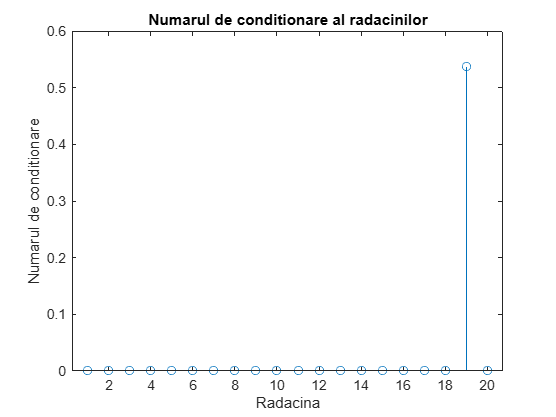

error with normal perturbation 0.000002


error with uniform perturbation 0.597973


valoare reala: 2.718282, valoare calculata: 2.718282


% polinomul x^n+x^(n-1) /2  +x^(n-2) /2^2 + ....
n = 20;
p = 2.^-(1:n); 

%radacinile
roots_exact = roots(p);

%calcul nr. de conditionare pt fiecare radacina
cond_numbers = zeros(n, 1);

%ca sa fie aleatoare dispersia
%ca sa fie uniforma:  unifrnd(1, n+1) * 1e-10
perturbation = normrnd(0,1e-10);

for i = 1:n
    p_perturbed = p;
    
    %de fiecare data perturb un coeficient
    p_perturbed(i) = p_perturbed(i) + perturbation;
    
    %aflam iar radacinile si conditionarea 
    %aka cat de mult o influentat perturbarea noastra rez final
    roots_perturbed = roots(p_perturbed);
    cond_numbers(i) = norm(roots_perturbed - roots_exact)/norm(roots_exact);
end

%graficul nr. de conditionare al fiecarei radacini
figure;
stem(1:n, cond_numbers);
title('Numarul de conditionare al radacinilor');
xlabel('Radacina');
ylabel('Numarul de conditionare');

%perturbarea cu variabile aleatoare normale
%init o perturbare care urmeaza distributie normala
perturbation_normal = normrnd(0,1) * 1e-10;
p_perturbed_normal = p + perturbation_normal;
roots_perturbed_normal = roots(p_perturbed_normal);
error_perturbed_normal = norm(roots_perturbed_normal-roots_exact)/norm(roots_exact);
fprintf('error with normal perturbation %f\n',error_perturbed_normal);

%perturbarea cu variabile aleatoare uniforme
%init o perturbare care urmeaza distributie uniforma
perturbation_uniform = unifrnd(1, n+1) * 1e-10;
p_perturbed_uniform = p + perturbation_uniform;
roots_perturbed_uniform = roots(p_perturbed_uniform);
error_perturbed_uniform = norm(roots_perturbed_uniform-roots_exact)/norm(roots_exact);
fprintf('error with uniform perturbation %f\n',error_perturbed_uniform);

syms x
format longg

n=10000;

%limita superioara a lui E este 1/(n+1)
E_n=1/(n+1);

%avem En si vrem E1 -> mergem invers
%En-1 = (1-  En-1) /n
for i=n:-1:2
    E_n = (1-E_n)/i;
end

%verificam comparativ cu valoarea reala
e_calculat = 1/E_n;
e_real = exp(1);

fprintf('valoare reala: %f, valoare calculata: %f\n', e_real, e_calculat);